# Test FESR from (https://github.com/ZeMA-gGmbH/LMT-ML-Toolbox)

clearvars;

addPaths;

%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

%Used Method
loadStruct.loadMethod = 1;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%SaveFlag = 
loadStruct.saveFlag = false;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

[data,target] = loadDataFull(loadStruct);

Data\sensorA.mat
acetone
Split
RandomFlag
   0



## TestFESR (Remember changing Path)

PLSRComp = 100;
tool = toolboxWrapper({@MultisensorExtractor, @Pearson, @NumFeatRanking, @PLSR}, {{@ALAExtractor}, {500}, {@Pearson,{@PLSR},{{PLSRComp}},@RMSE.loss}, {PLSRComp}});
tool.train(data.train,target.train);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


pred = tool.apply(data.test);

disp(helpers.RMSE.loss(pred,target.test));

   26.0140



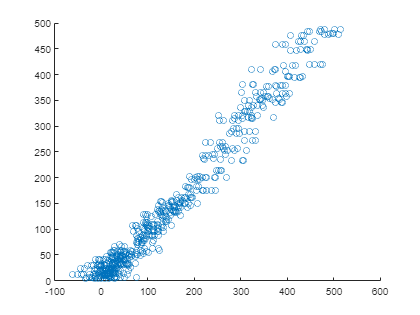

figure()
scatter(pred,target.test)